# Rugularized Logistic Regression Application

## Rugularized Logistic Regression Application On Real Data

### 1. Dataset

The file `wine.csv `contains the information related to red wine, various factors affecting the quality.

For a given wine, we would like to predict whether it is of good or bad quality. So the task we have to perform is a classification and knowing that in this case, the label consists of only two different classes, thus it is a binary classification.

clear
X = readtable('wine.csv'); % Load comma separated data

summary(X) % Summary of data

Variables:

    fixedAcidity: 1599×1 double

        Properties:
            Description:  fixed acidity
        Values:

            Min          4.6  
            Median       7.9  
            Max         15.9  

    volatileAcidity: 1599×1 double

        Properties:
            Description:  volatile acidity
        Values:

            Min         0.12  
            Median      0.52  
            Max         1.58  

    citricAcid: 1599×1 double

        Properties:
            Description:  citric acid
        Values:

            Min            0  
            Median      0.26  
            Max            1  

    residualSugar: 1599×1 double

        Properties:
            Description:  residual sugar
        Values:

            Min          0.9  
            Median       2.2  
            Max         15.5  

    chlorides: 1599×1 double

        Properties:
            Description:  chlorid

X(1:5,:) % 5 first examples of data set

ans = 5×12 table
    fixedAcidity    volatileAcidity    citricAcid    residualSugar    chlorides    freeSulfurDioxide    totalSulfurDioxide    density     pH     sulphates    alcohol    quality 
    ____________    _______________    __________    _____________    _________    _________________    __________________    _______    ____    _________    _______    ________

         7.4              0.7                0            1.9           0.076             11                    34            0.9978     3.51      0.56         9.4      {'bad' }
         7.8             0.88           

### 2. Pre-processing

#### 2.1 Label encoding

We start with encoding the labels of our classification, 'bad' quality is encoded as 0 and 'good' quality as 1.

[~, n] = size(X);
X.quality = categorical(X.quality);

% Seperate labels
y = (X{:,"quality"} == 'good'); 
X = X(:,1:n-1);
n = n-1; % Number of features

#### 2.2 Cross-Validation

The data is splitted to 3 parts as follows : 60% training set, 20% validation set and 20% test set.

% Training, 60% of dataset
TrainX = X{1:960,:}; 
Trainy = y(1:960,:);
Trainm = size(TrainX,1); % Number of examples in training set

% Cross-Validation, 20% of dataset
ValidationX = X{961:1280,:};
Validationy = y(961:1280,:);
Validm = size(ValidationX,1); % Number of examples in validation set

% Test, 20% of dataset
TestX = X{1281:end,:};
Testy = y(1281:end,:);
Testm = size(TestX,1); % Number of examples in test set

#### 2.3 Feature standardization

By looking at the values of features, we note that there are much differences between orders of magnitudes . Feature standardization can make gradient descent converge much more quickly.

[TrainX, mu, sigma] = featureStandardize(TrainX); % Scale training set features and set them to zero mean
% Add intercept term to TrainX
TrainX = [ones(Trainm, 1) TrainX];

It is important to store the values used for standardization of training test - the mean value and the standard deviation - in order to be able to standardize validation and test set.

ValidationX = (ValidationX - mu)./sigma; % Scale validation set features and set them to zero mean
% Add intercept term to TrainX
ValidationX = [ones(Validm, 1) ValidationX];

TestX = (TestX - mu)./sigma; % Scale validation set features and set them to zero mean
% Add intercept term to TestX
TestX = [ones(Testm, 1) TestX];

### 3. Selecting hyper-parameters

#### 3.1 Selecting best learning rate

In order to find the best learning rate, we train a few models with different learning rate in parallel. Then only we select the one that works better at the end on our validation set.

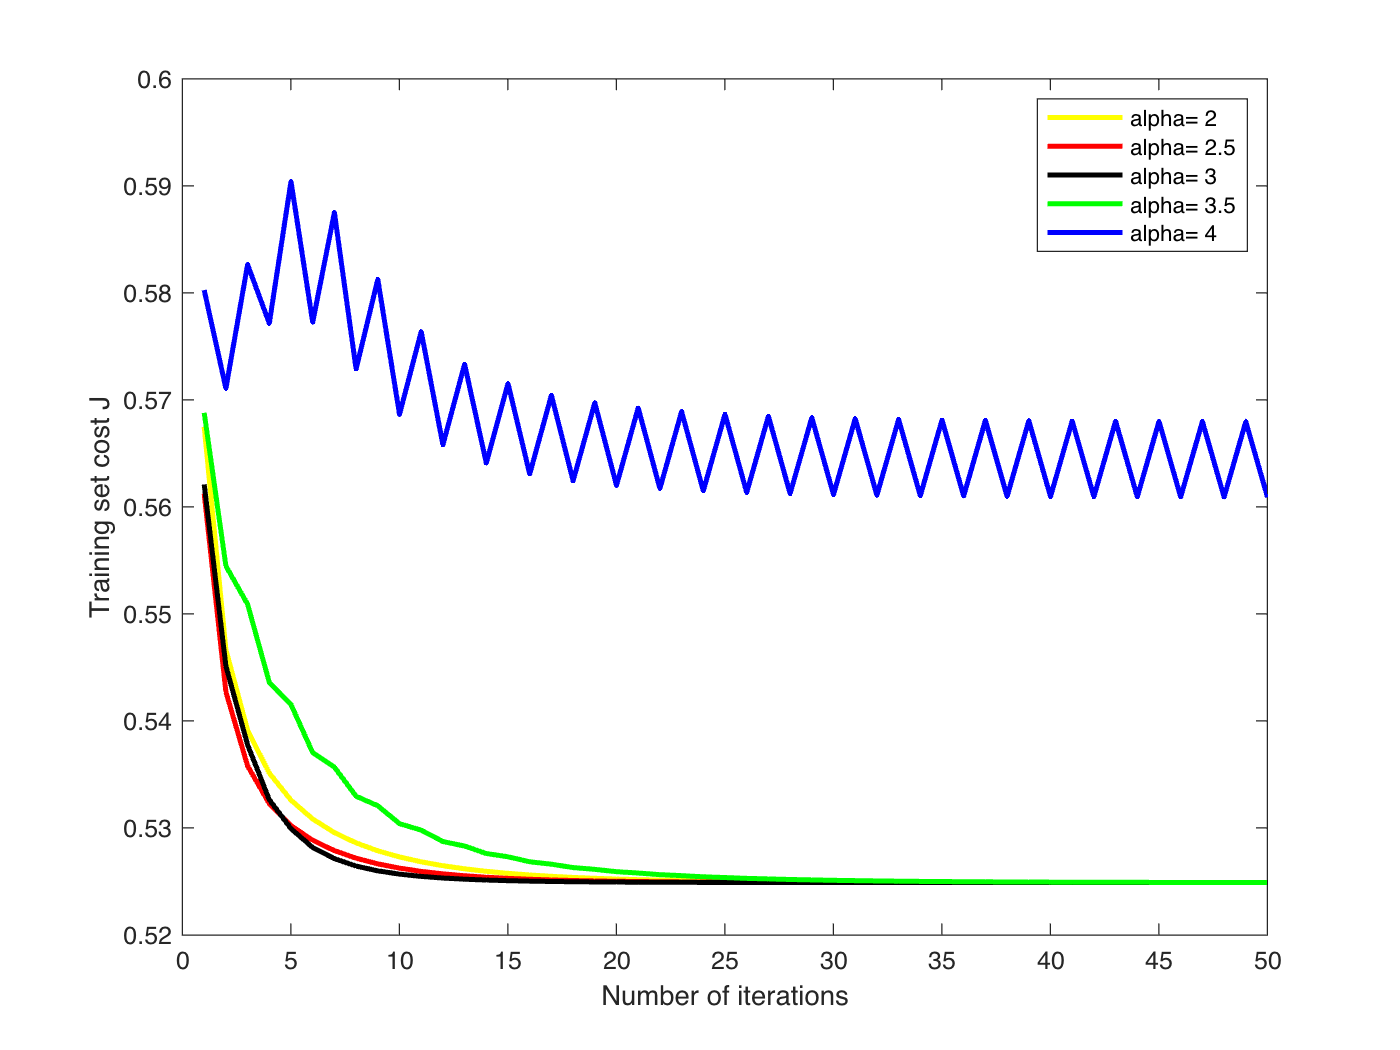

% Initialize theta
theta = zeros(n+1, 1);
iteration_max = 50;
lambda = 1;

% Choose some values for alpha
alpha_1 = 2;
alpha_2 = 2.5;
alpha_3 = 3;
alpha_4 = 3.5;
alpha_5 = 4;

% Train models with different learning rate in parallel
[theta_1, J1_history] = gradientDescent(TrainX, Trainy, theta, alpha_1, iteration_max, lambda);
[theta_2, J2_history] = gradientDescent(TrainX, Trainy, theta, alpha_2, iteration_max, lambda);
[theta_3, J3_history] = gradientDescent(TrainX, Trainy, theta, alpha_3, iteration_max, lambda);
[theta_4, J4_history] = gradientDescent(TrainX, Trainy, theta, alpha_4, iteration_max, lambda);
[theta_5, J5_history] = gradientDescent(TrainX, Trainy, theta, alpha_5, iteration_max, lambda);

% Plot the convergence graph
figure
plot(1:iteration_max, J1_history, '-y', 'LineWidth', 2);
hold on
plot(1:iteration_max, J2_history, '-r', 'LineWidth', 2);
plot(1:iteration_max, J3_history, '-k', 'LineWidth', 2);
plot(1:iteration_max, J4_history, '-g', 'LineWidth', 2);
plot(1:iteration_max, J5_history, '-b', 'LineWidth', 2);
legend('alpha= 2', 'alpha= 2.5','alpha= 3', 'alpha= 3.5', 'alpha= 4')
hold off
xlabel('Number of iterations');
ylabel('Training set cost J');

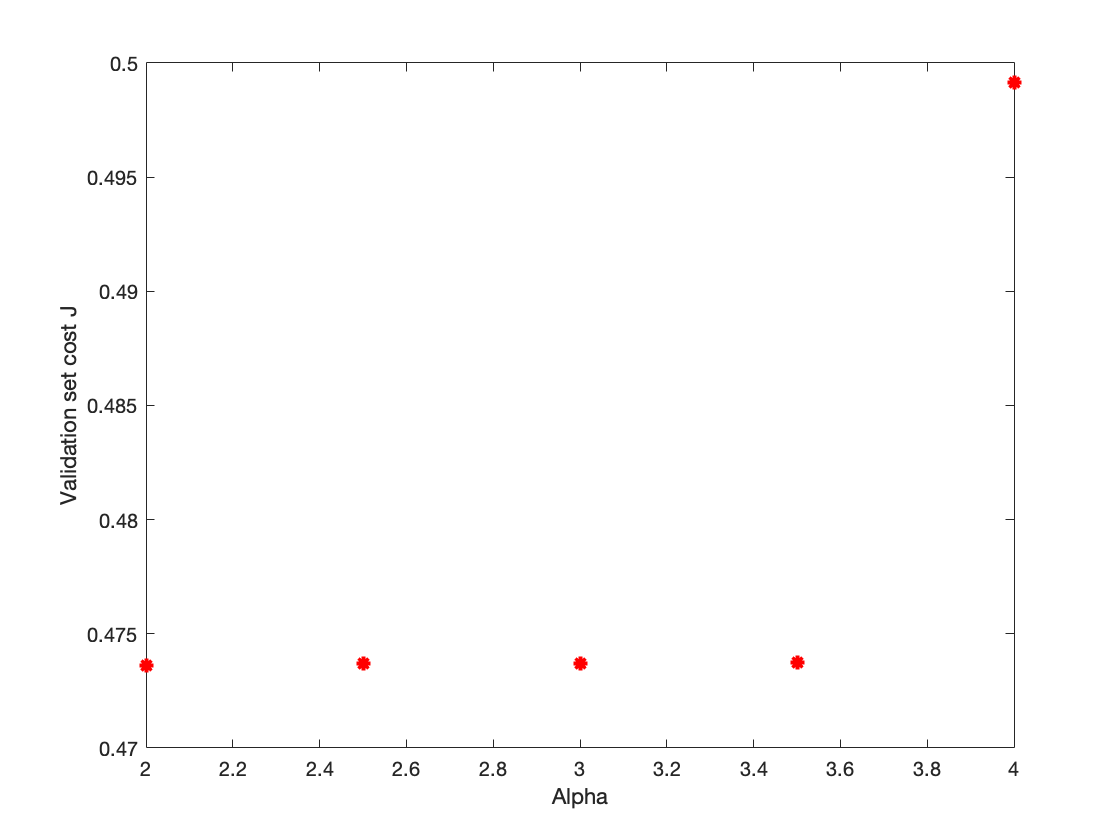

figure
plot(alpha_1, costFunction(theta_1, ValidationX, Validationy, lambda),'*r', 'LineWidth', 2);
hold on
plot(alpha_2, costFunction(theta_2, ValidationX, Validationy, lambda),'*r', 'LineWidth', 2);
plot(alpha_3, costFunction(theta_3, ValidationX, Validationy, lambda),'*r', 'LineWidth', 2);
plot(alpha_4, costFunction(theta_4, ValidationX, Validationy, lambda),'*r', 'LineWidth', 2);
plot(alpha_5, costFunction(theta_5, ValidationX, Validationy, lambda),'*r', 'LineWidth', 2);

hold off
xlabel('Alpha');
ylabel('Validation set cost J');

It can be noticed that the best learning rate is approximately 2.5 and with maximum iteration of 30, the curve reaches the minimum possible cost.

best_alpha = alpha_2;
iteration_max = 30;

#### 3.2 Selecting best **regularization rate**

Same as finding the best learning rate, we train a few models with different regularization rate in parallel and select the one that works better on our validation set.

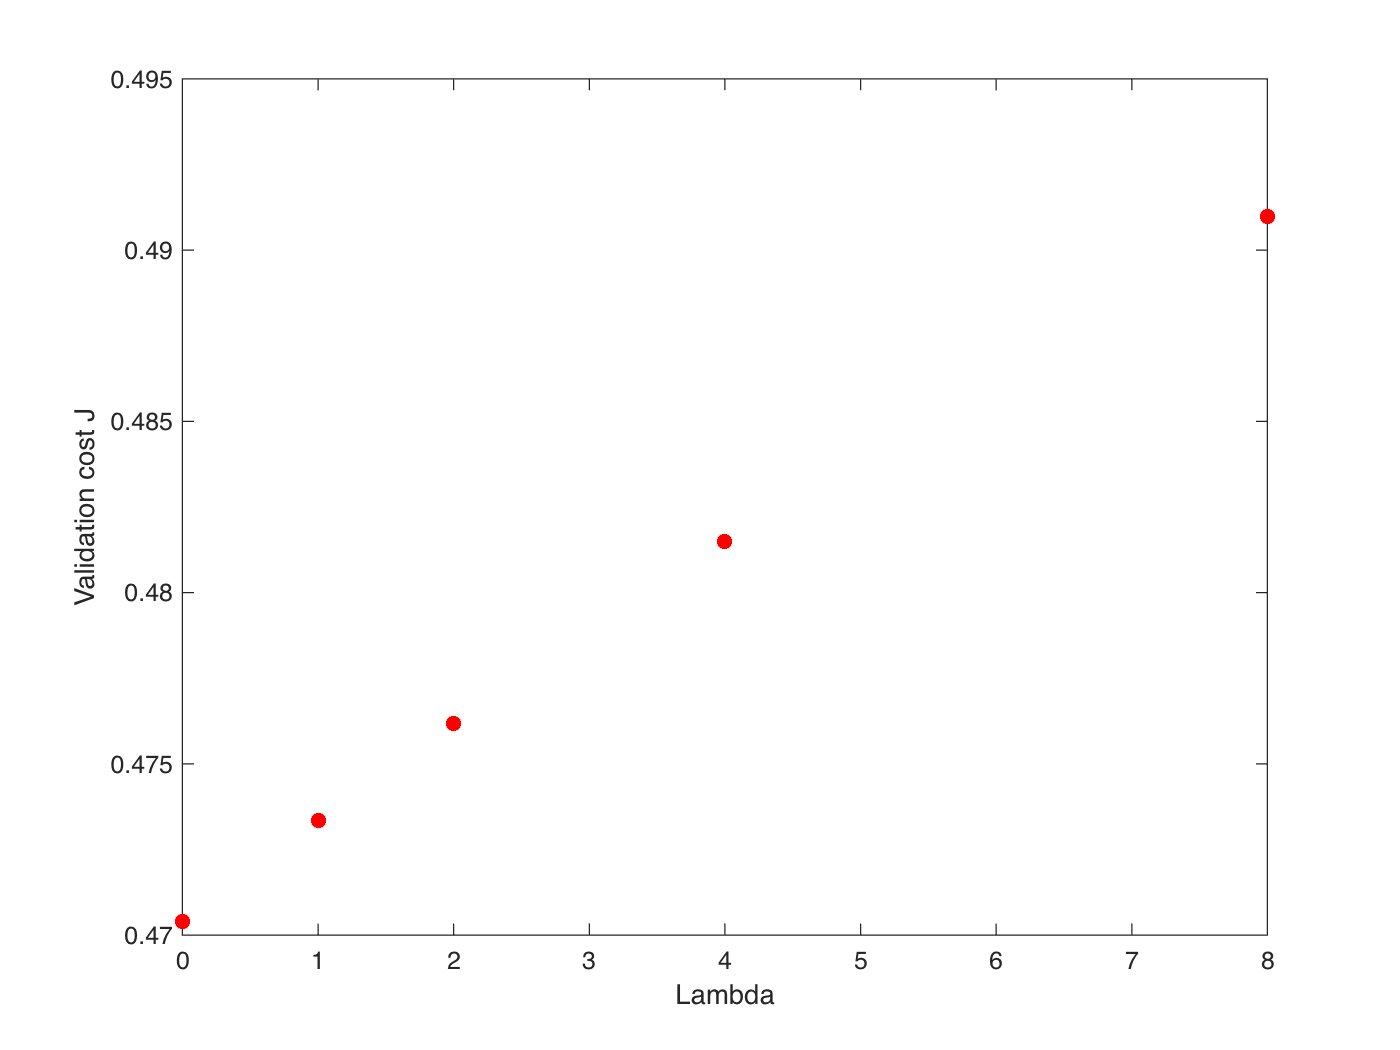

% Choose some values for lambda
lambda_1 = 0;
lambda_2 = 1;
lambda_3 = 2;
lambda_4 = 4;
lambda_5 = 8;

% Train models with different regularization rate in parallel
[theta_1, ~] = gradientDescent(TrainX, Trainy, theta, best_alpha, iteration_max, lambda_1);
[theta_2, ~] = gradientDescent(TrainX, Trainy, theta, best_alpha, iteration_max, lambda_2);
[theta_3, ~] = gradientDescent(TrainX, Trainy, theta, best_alpha, iteration_max, lambda_3);
[theta_4, ~] = gradientDescent(TrainX, Trainy, theta, best_alpha, iteration_max, lambda_4);
[theta_5, ~] = gradientDescent(TrainX, Trainy, theta, best_alpha, iteration_max, lambda_5);


% Plot
figure
plot(lambda_1, costFunction(theta_1, ValidationX, Validationy, lambda_1),'*r', 'LineWidth', 2);
hold on
plot(lambda_2, costFunction(theta_2, ValidationX, Validationy, lambda_2),'*r', 'LineWidth', 2);
plot(lambda_3, costFunction(theta_3, ValidationX, Validationy, lambda_3),'*r', 'LineWidth', 2);
plot(lambda_4, costFunction(theta_4, ValidationX, Validationy, lambda_4),'*r', 'LineWidth', 2);
plot(lambda_5, costFunction(theta_5, ValidationX, Validationy, lambda_5),'*r', 'LineWidth', 2);
hold off
xlabel('Lambda');
ylabel('Validation cost J');

It can be noticed that the lowest cost on the validation set is when regularization rate is equal to 0. In other words, fitting the parameters without regularization.

best_lambda = lambda_1;
theta = theta_1;

### 4. Computing accuracy

#### 4.1 Training set accuracy

p = predict(theta, TrainX);
fprintf('Training Accuracy: %f\n', mean(double(p == Trainy)) * 100);

Training Accuracy: 74.062500


#### 4.2 Validation set accuracy

p = predict(theta, ValidationX);
fprintf('Validation Accuracy: %f\n', mean(double(p == Validationy)) * 100);

Validation Accuracy: 78.437500


#### 4.3 Test set accuracy

p = predict(theta, TestX);
fprintf('Test Accuracy: %f\n', mean(double(p == Testy)) * 100);

Test Accuracy: 74.294671


### 5. Conclusion

Knowing that we don't notice a considerable difference between the training set accuracy and test set accuracy, it can be deduced that there is no overfitting in our model.

However, the model suffers from underfitting (high-bias + low variance). This problem would be solved by adding polynomal features or using a more complex model such as Decision Tree.